**Time Series Figure (02/03-02/10) MASS, PM Resolved**

clear, close all

**Import data from Excel:**

%SMPS
file1=   'PMSizeResolvedDataFeb.xlsx'

file1 = 'PMSizeResolvedDataFeb.xlsx'

sheet1=  'Sheet1'

sheet1 = 'Sheet1'

PM0_5=  xlsread(file1,sheet1,'B3:DRJ3')

PM0_5 =     1.4838    1.4002    1.3760    1.3420    1.3317    1.3579    1.1315    1.1632    1.2815    1.2729    1.1644    1.0675    0.9811    1.0384    1.1329    1.1383    1.0328    1.0834    0.9384    0.9981    0.9313    0.9940    0.9300    0.8461    1.0044    0.9842    1.1209    1.0849    1.0655    1.0635    1.1563    1.0914    1.1641    1.0342    1.1074    1.0802    1.0212    1.1467    0.8551    1.1378    0.9724    0.8959    0.9210    0.8650    0.8280    0.8599    0.8274    0.8783    0.8278    0.7483


PM0_1=  xlsread(file1,sheet1,'B4:DRJ4')

PM0_1 =     0.4812    0.4286    0.4100    0.3693    0.3503    0.3199    0.3028    0.3728    0.4395    0.3656    0.3586    0.3329    0.3232    0.2831    0.4215    0.3801    0.3404    0.3049    0.3067    0.2785    0.2618    0.2499    0.2399    0.2382    0.2379    0.2247    0.2269    0.2246    0.2179    0.2217    0.2133    0.2102    0.2135    0.2057    0.1953    0.1957    0.1961    0.1852    0.1819    0.1833    0.1775    0.1667    0.1786    0.1674    0.1661    0.1648    0.1645    0.1577    0.1511    0.1494



t_MST_SMPStable= readtable('PMSizeResolvedDataFeb.xlsx','Range', 'B1:DRJ1','VariableNamingRule','Preserve')

t_MST_SMPStable = 1×3181 table
            Var1                    Var2                    Var3                    Var4                    Var5                    Var6                    Var7                    Var8                    Var9                   Var10                   Var11                   Var12                   Var13                   Var14                   Var15                   Var16                   Var17                   Var18                   Var19                   Var20                   Var21                   Var22                   Var23                   Var24</

t_MST_SMPSArray=  table2array(t_MST_SMPStable) %turning time table into array

t_MST_SMPSArray = 1×3181 datetime array
Columns 1 through 434

   Feb/03/2022 06:21:00   Feb/03/2022 06:24:00   Feb/03/2022 06:27:00   Feb/03/2022 06:30:00   Feb/03/2022 06:33:00   Feb/03/2022 06:36:00   Feb/03/2022 06:39:00   Feb/03/2022 06:42:00   Feb/03/2022 06:45:00   Feb/03/2022 06:48:00   Feb/03/2022 06:51:00   Feb/03/2022 06:54:00   Feb/03/2022 06:57:00   Feb/03/2022 07:00:00   Feb/03/2022 07:03:00   Feb/03/2022 07:06:00   Feb/03/2022 07:09:00   Feb/03/2022 07:12:00   Feb/03/2022 07:15:00   Feb/03/2022 07:18:00   Feb/03/2022 07:21:00   Feb/03/2022 07:24:00   Feb/03/2022 07:27:00   Feb/03/2022 07:30:00   Feb/03/2022 07:33:00   Feb/03/2022 07:36:00   Feb/03/2022 07:39:00   Feb/03/2022 07:42:00   Feb/03/2022 07:45:00   Feb/03/2022 07:48:00   Feb/03/2022 07:51:00   Feb/03/2022 07:54:00   Feb/03/2022 07:57:00   Feb/03/2022 08:00:00   Feb/03/2022 08:03:00   Feb/03/2022 08:06:00   Feb/03/2022 08:09:00   Feb/03/2022 08:12:00   Feb/03/2022 08:15:00   Feb/03/2022 08:18:00   Feb/03/2022 08

t_MST_SMPS= datetime(t_MST_SMPSArray,'InputFormat','yyyy-MM-dd HH:mm:ss z','TimeZone','America/Denver')

t_MST_SMPS = 1×3181 datetime array
Columns 1 through 434

   Feb/03/2022 06:21:00   Feb/03/2022 06:24:00   Feb/03/2022 06:27:00   Feb/03/2022 06:30:00   Feb/03/2022 06:33:00   Feb/03/2022 06:36:00   Feb/03/2022 06:39:00   Feb/03/2022 06:42:00   Feb/03/2022 06:45:00   Feb/03/2022 06:48:00   Feb/03/2022 06:51:00   Feb/03/2022 06:54:00   Feb/03/2022 06:57:00   Feb/03/2022 07:00:00   Feb/03/2022 07:03:00   Feb/03/2022 07:06:00   Feb/03/2022 07:09:00   Feb/03/2022 07:12:00   Feb/03/2022 07:15:00   Feb/03/2022 07:18:00   Feb/03/2022 07:21:00   Feb/03/2022 07:24:00   Feb/03/2022 07:27:00   Feb/03/2022 07:30:00   Feb/03/2022 07:33:00   Feb/03/2022 07:36:00   Feb/03/2022 07:39:00   Feb/03/2022 07:42:00   Feb/03/2022 07:45:00   Feb/03/2022 07:48:00   Feb/03/2022 07:51:00   Feb/03/2022 07:54:00   Feb/03/2022 07:57:00   Feb/03/2022 08:00:00   Feb/03/2022 08:03:00   Feb/03/2022 08:06:00   Feb/03/2022 08:09:00   Feb/03/2022 08:12:00   Feb/03/2022 08:15:00   Feb/03/2022 08:18:00   Feb/03/2022 08:21:0


%APS
PM1=  xlsread(file1,sheet1,'B20:DRJ20')

PM1 =     2.0828    1.9456    1.9066    1.8333    1.7940    1.7794    1.5271    1.6223    1.8165    1.7255    1.6044    1.4822    1.3830    1.3994    1.6257    1.5944    1.4674    1.4713    1.3299    1.3654    1.2814    1.3220    1.2535    1.1690    1.3287    1.2947    1.4489    1.4003    1.3794    1.3788    1.4723    1.4077    1.4764    1.3427    1.4064    1.3688    1.3057    1.4241    1.1179    1.4052    1.2367    1.1483    1.1897    1.1155    1.0782    1.1047    1.0670    1.1177    1.0519    0.9732


PM2_5=  xlsread(file1,sheet1,'B19:DRJ19')

PM2_5 =     2.4734    2.3485    2.3574    2.2748    2.1312    2.0579    1.7883    1.8140    2.0560    1.9127    1.7720    1.6717    1.5746    1.5447    1.7589    1.8056    1.6689    1.5895    1.5185    1.5282    1.4171    1.4445    1.3846    1.2892    1.4907    1.4013    1.6013    1.5779    1.5312    1.4864    1.6136    1.5222    1.6060    1.5050    1.5555    1.4976    1.4184    1.5538    1.2295    1.5217    1.3746    1.2685    1.3215    1.1893    1.2041    1.2332    1.2038    1.2257    1.1504    1.0650


PM10=  xlsread(file1,sheet1,'B18:DRJ18')

PM10 =     4.2458    4.1648    4.6493    3.0398    2.5769    2.3519    2.0084    2.0286    2.1373    2.0314    2.0015    1.7602    1.7849    1.6985    1.7879    1.9360    1.7644    1.6844    1.5282    1.6204    1.4788    1.4541    1.6849    1.3776    1.5676    1.5794    1.7223    1.8165    1.6053    1.5707    1.6803    1.5755    1.6586    1.5515    1.6433    1.5477    1.4597    1.5942    1.2934    1.5314    1.4111    1.3648    1.4196    1.2411    1.2702    1.3397    1.2800    1.2702    1.2012    1.1429



t_MST_APStable= readtable('PMSizeResolvedDataFeb.xlsx','Range', 'B11:DRJ11','VariableNamingRule','Preserve')

t_MST_APStable = 1×3181 table
            Var1                    Var2                    Var3                    Var4                    Var5                    Var6                    Var7                    Var8                    Var9                   Var10                   Var11                   Var12                   Var13                   Var14                   Var15                   Var16                   Var17                   Var18                   Var19                   Var20                   Var21                   Var22                   Var23                   Var24

t_MST_APSArray=  table2array(t_MST_APStable) %turning time table into array

t_MST_APSArray = 1×3181 datetime array
Columns 1 through 434

   Feb/03/2022 06:21:00   Feb/03/2022 06:24:00   Feb/03/2022 06:27:00   Feb/03/2022 06:30:00   Feb/03/2022 06:33:00   Feb/03/2022 06:36:00   Feb/03/2022 06:39:00   Feb/03/2022 06:42:00   Feb/03/2022 06:45:00   Feb/03/2022 06:48:00   Feb/03/2022 06:51:00   Feb/03/2022 06:54:00   Feb/03/2022 06:57:00   Feb/03/2022 07:00:00   Feb/03/2022 07:03:00   Feb/03/2022 07:06:00   Feb/03/2022 07:09:00   Feb/03/2022 07:12:00   Feb/03/2022 07:15:00   Feb/03/2022 07:18:00   Feb/03/2022 07:21:00   Feb/03/2022 07:24:00   Feb/03/2022 07:27:00   Feb/03/2022 07:30:00   Feb/03/2022 07:33:00   Feb/03/2022 07:36:00   Feb/03/2022 07:39:00   Feb/03/2022 07:42:00   Feb/03/2022 07:45:00   Feb/03/2022 07:48:00   Feb/03/2022 07:51:00   Feb/03/2022 07:54:00   Feb/03/2022 07:57:00   Feb/03/2022 08:00:00   Feb/03/2022 08:03:00   Feb/03/2022 08:06:00   Feb/03/2022 08:09:00   Feb/03/2022 08:12:00   Feb/03/2022 08:15:00   Feb/03/2022 08:18:00   Feb/03/2022 08:

t_MST_APS= datetime(t_MST_APSArray,'InputFormat','yyyy-MM-dd HH:mm:ss z','TimeZone','America/Denver')

t_MST_APS = 1×3181 datetime array
Columns 1 through 434

   Feb/03/2022 06:21:00   Feb/03/2022 06:24:00   Feb/03/2022 06:27:00   Feb/03/2022 06:30:00   Feb/03/2022 06:33:00   Feb/03/2022 06:36:00   Feb/03/2022 06:39:00   Feb/03/2022 06:42:00   Feb/03/2022 06:45:00   Feb/03/2022 06:48:00   Feb/03/2022 06:51:00   Feb/03/2022 06:54:00   Feb/03/2022 06:57:00   Feb/03/2022 07:00:00   Feb/03/2022 07:03:00   Feb/03/2022 07:06:00   Feb/03/2022 07:09:00   Feb/03/2022 07:12:00   Feb/03/2022 07:15:00   Feb/03/2022 07:18:00   Feb/03/2022 07:21:00   Feb/03/2022 07:24:00   Feb/03/2022 07:27:00   Feb/03/2022 07:30:00   Feb/03/2022 07:33:00   Feb/03/2022 07:36:00   Feb/03/2022 07:39:00   Feb/03/2022 07:42:00   Feb/03/2022 07:45:00   Feb/03/2022 07:48:00   Feb/03/2022 07:51:00   Feb/03/2022 07:54:00   Feb/03/2022 07:57:00   Feb/03/2022 08:00:00   Feb/03/2022 08:03:00   Feb/03/2022 08:06:00   Feb/03/2022 08:09:00   Feb/03/2022 08:12:00   Feb/03/2022 08:15:00   Feb/03/2022 08:18:00   Feb/03/2022 08:21:00

**Graphical parameters:**

Find colors and RGB codes at www.colorspire.com/rgb-color-wheel

LW = 2    %Line thickness for plots

LW = 2

FS = 16     %Font size

FS = 16

**RBG color set (a subset from the RBG xkcd function)**

%Reds:
rosa	 =[0.996078431	0.525490196	0.643137255]

rosa =     0.9961    0.5255    0.6431


lipstick = [213/255 23/255 78/255]

lipstick =     0.8353    0.0902    0.3059


redwine	= [0.549019608	0	0.203921569]

redwine =     0.5490         0    0.2039



%Yellows:
peach = [1 176/255 124/255]

peach =     1.0000    0.6902    0.4863


orangish	 =[0.988235294	0.509803922	0.290196078]

orangish =     0.9882    0.5098    0.2902


toupe = [0.780392157	0.674509804	0.490196078]

toupe =     0.7804    0.6745    0.4902


sunyellow =[1	0.874509804	0.133333333]

sunyellow =     1.0000    0.8745    0.1333



%Greens:
leaf	 =[0.443137255	0.666666667	0.203921569]

leaf =     0.4431    0.6667    0.2039


green = [62/255 164/255 86/255] 

green =     0.2431    0.6431    0.3373


spruce = [0.039215686 0.37254902 0.219607843]

spruce =     0.0392    0.3725    0.2196



%Blues:
waterblue	 =[0.054901961	0.529411765	0.8]

waterblue =     0.0549    0.5294    0.8000


blue = [0/255 118/255 168/255]

blue =          0    0.4627    0.6588


darkblue = [24/255 93/255 122/255]

darkblue =     0.0941    0.3647    0.4784


lightblue = [79/255 166/255 203/255]

lightblue =     0.3098    0.6510    0.7961



%Purples:
lightpurple = [219/255 178/255 209/255] 

lightpurple =     0.8588    0.6980    0.8196


purple	= [0.596078431	0.247058824	0.698039216]

purple =     0.5961    0.2471    0.6980


royalpurple = [75/255 0 110/255]

royalpurple =     0.2941         0    0.4314


**Plotting Just Cleaning:**

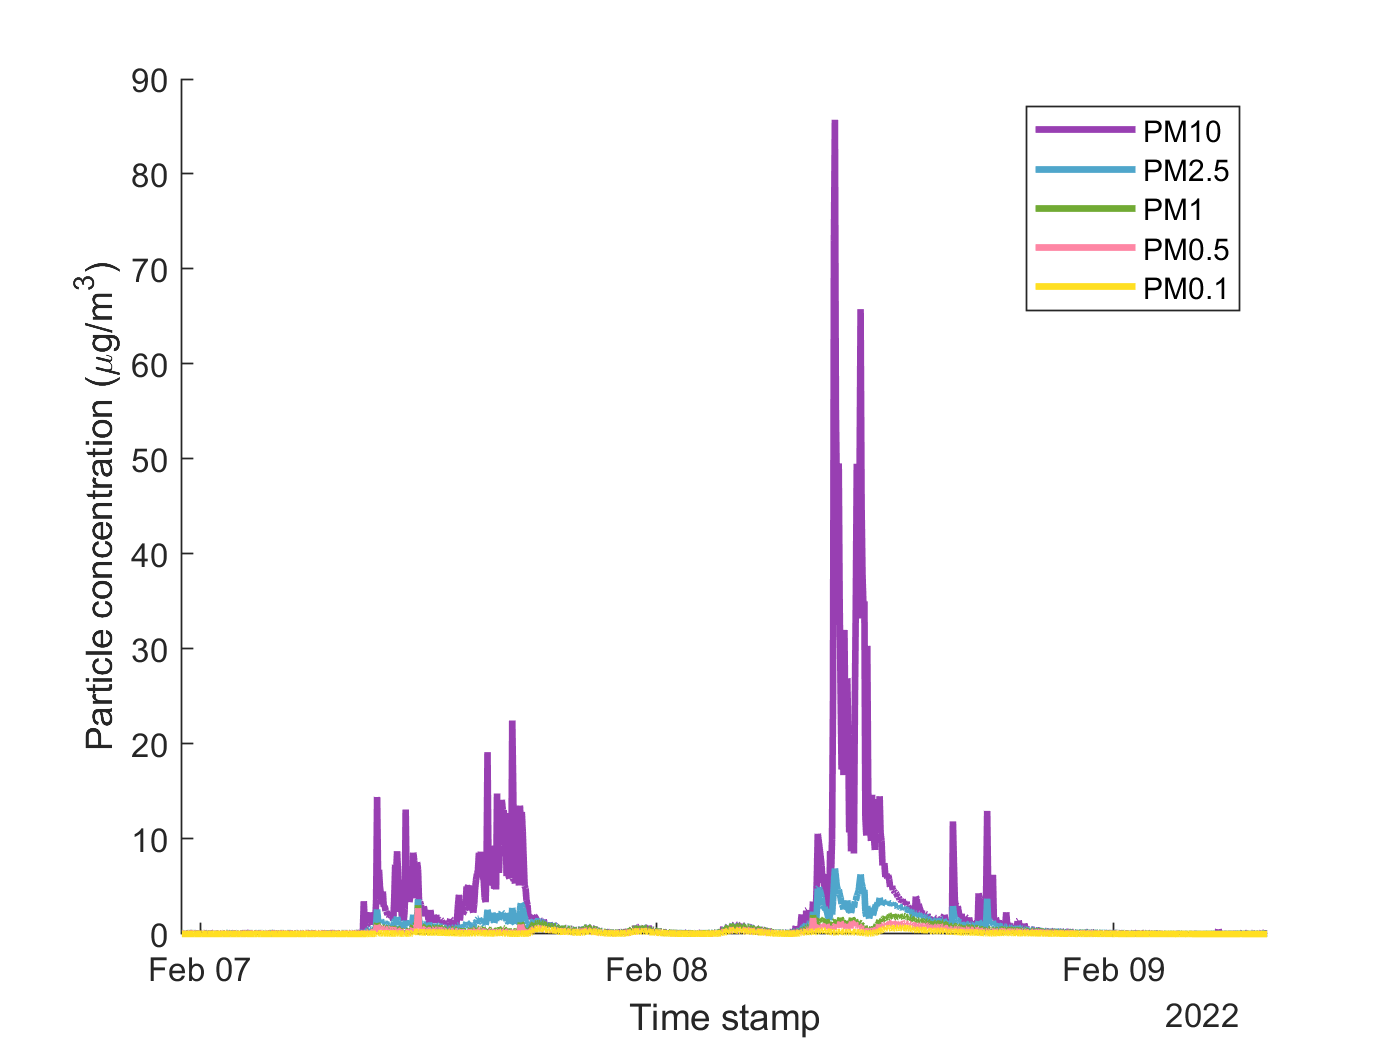

figure(1)
hold on
plot(t_MST_APS,PM10,'LineWidth',LW,'Color',purple)
plot(t_MST_APS,PM2_5,'LineWidth',LW,'Color',lightblue)
plot(t_MST_APS,PM1,'LineWidth',LW,'Color',leaf)
plot(t_MST_SMPS,PM0_5,'LineWidth',LW,'Color',rosa)
plot(t_MST_SMPS,PM0_1,'LineWidth',LW,'Color',sunyellow)

xlabel('Time stamp')
ylabel('Particle concentration (\mug/m^3)')

xlim([datetime(2022,2,6,23,03,0,'TimeZone','America/Denver')...
      datetime(2022,2,9,8,03,0,'TimeZone','America/Denver')])

legend('PM10', 'PM2.5', 'PM1', 'PM0.5', 'PM0.1')

hold off

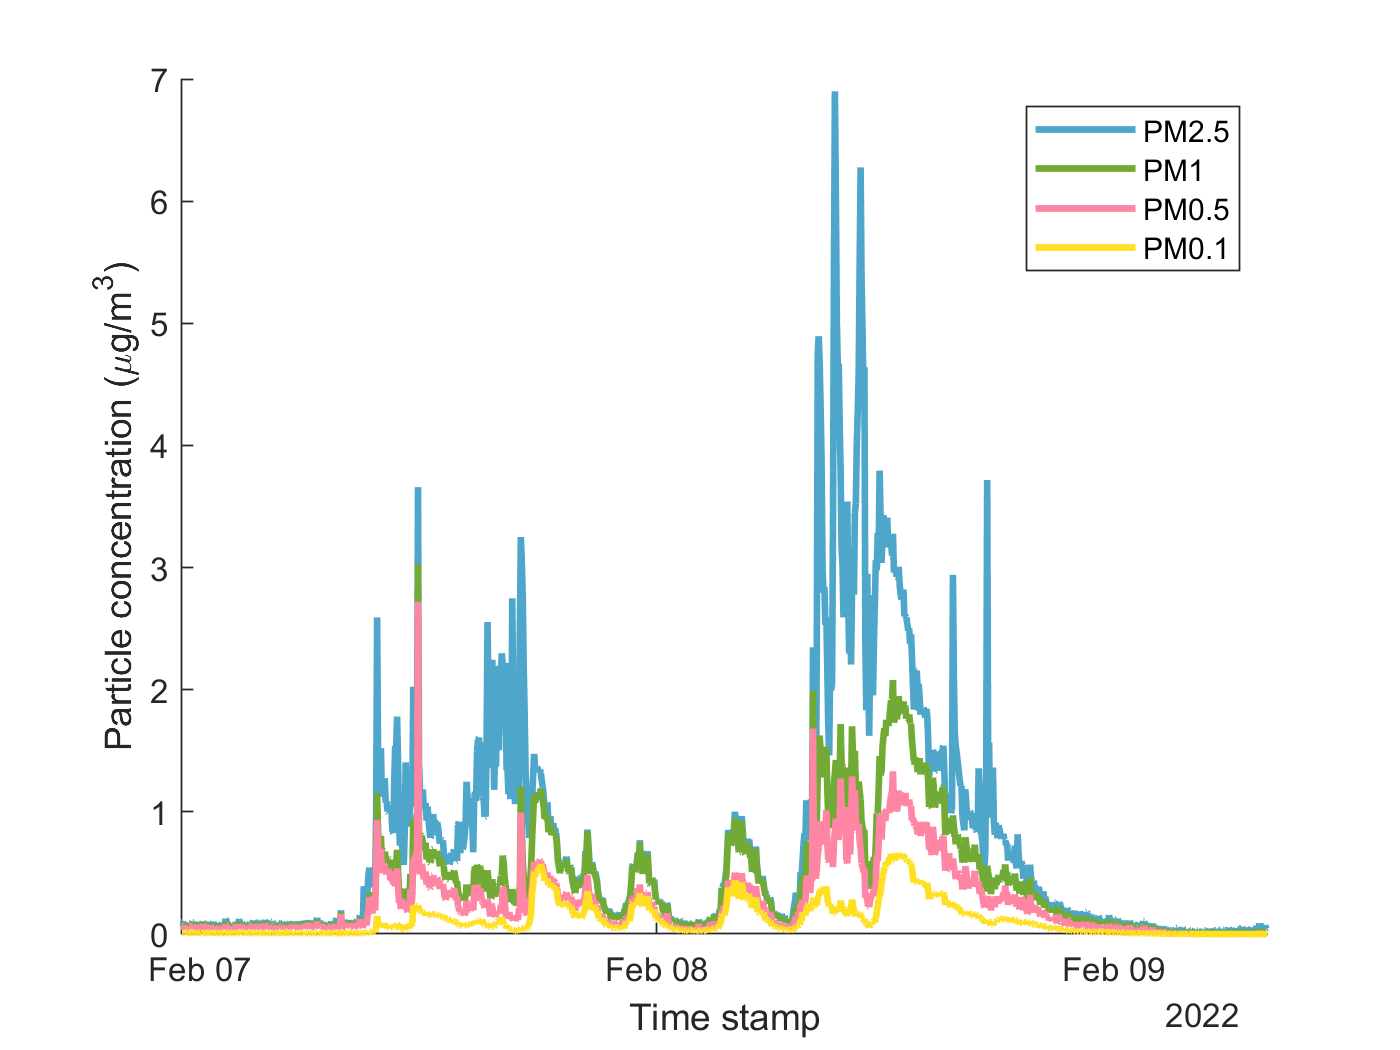

figure(2)
hold on
plot(t_MST_APS,PM2_5,'LineWidth',LW,'Color',lightblue)
plot(t_MST_APS,PM1,'LineWidth',LW,'Color',leaf)
plot(t_MST_SMPS,PM0_5,'LineWidth',LW,'Color',rosa)
plot(t_MST_SMPS,PM0_1,'LineWidth',LW,'Color',sunyellow)

xlabel('Time stamp')
ylabel('Particle concentration (\mug/m^3)')

xlim([datetime(2022,2,6,23,03,0,'TimeZone','America/Denver')...
      datetime(2022,2,9,8,03,0,'TimeZone','America/Denver')])

legend('PM2.5', 'PM1', 'PM0.5', 'PM0.1')

hold off

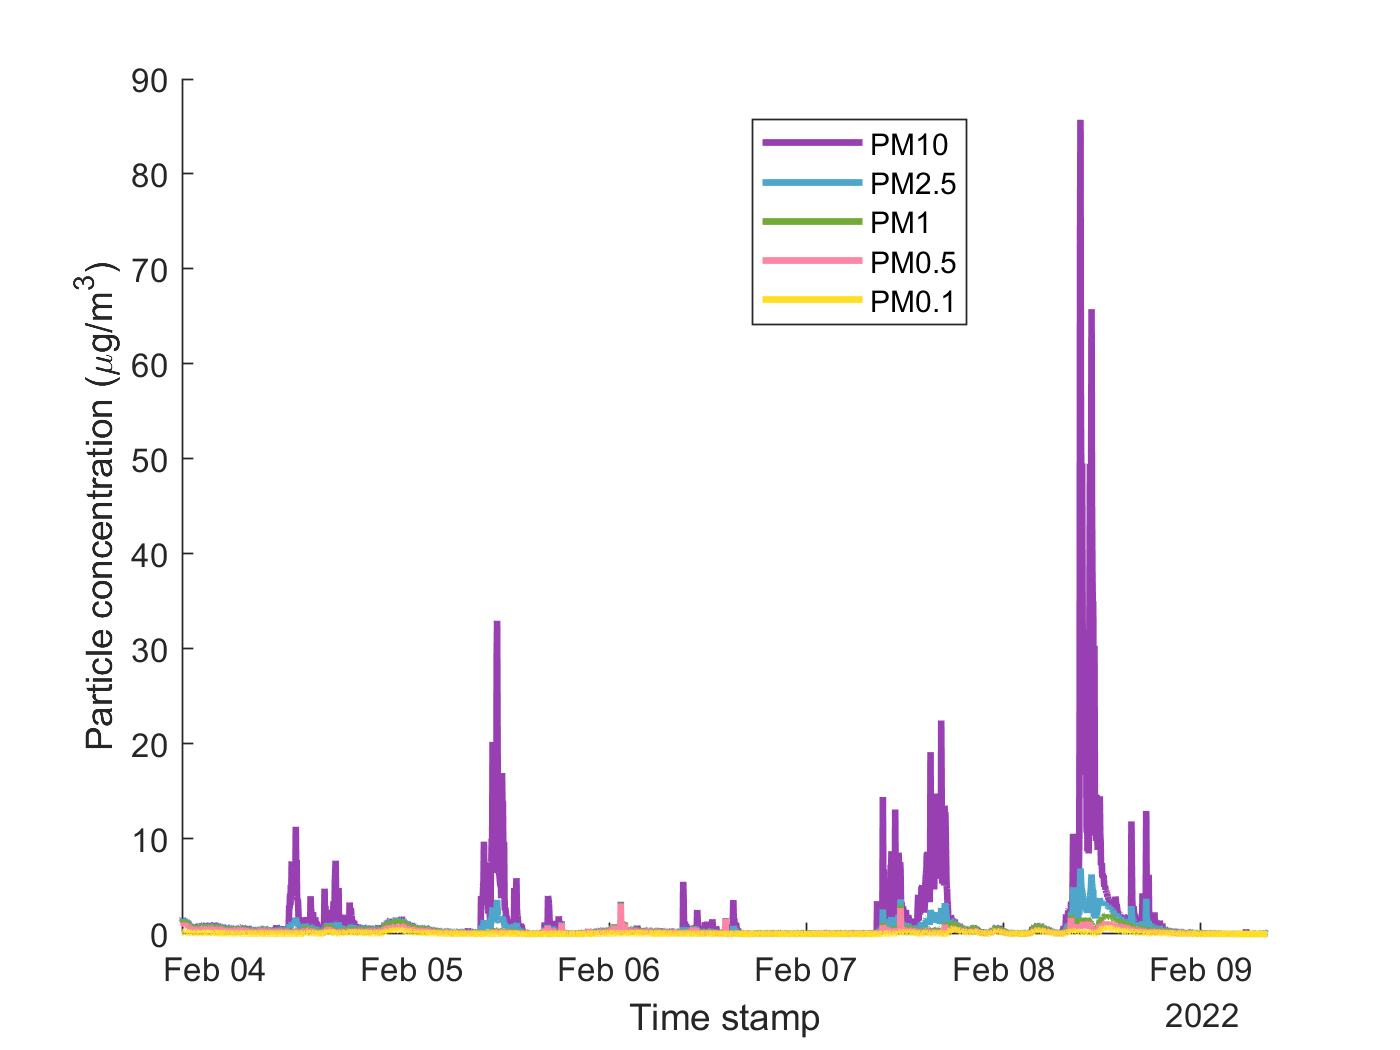

figure(3)
hold on
plot(t_MST_APS,PM10,'LineWidth',LW,'Color',purple)
plot(t_MST_APS,PM2_5,'LineWidth',LW,'Color',lightblue)
plot(t_MST_APS,PM1,'LineWidth',LW,'Color',leaf)
plot(t_MST_SMPS,PM0_5,'LineWidth',LW,'Color',rosa)
plot(t_MST_SMPS,PM0_1,'LineWidth',LW,'Color',sunyellow)

xlabel('Time stamp')
ylabel('Particle concentration (\mug/m^3)')

xlim([datetime(2022,2,3,20,00,0,'TimeZone','America/Denver')...
      datetime(2022,2,9,8,03,0,'TimeZone','America/Denver')])

legend('PM10', 'PM2.5', 'PM1', 'PM0.5', 'PM0.1','location','best')

hold off

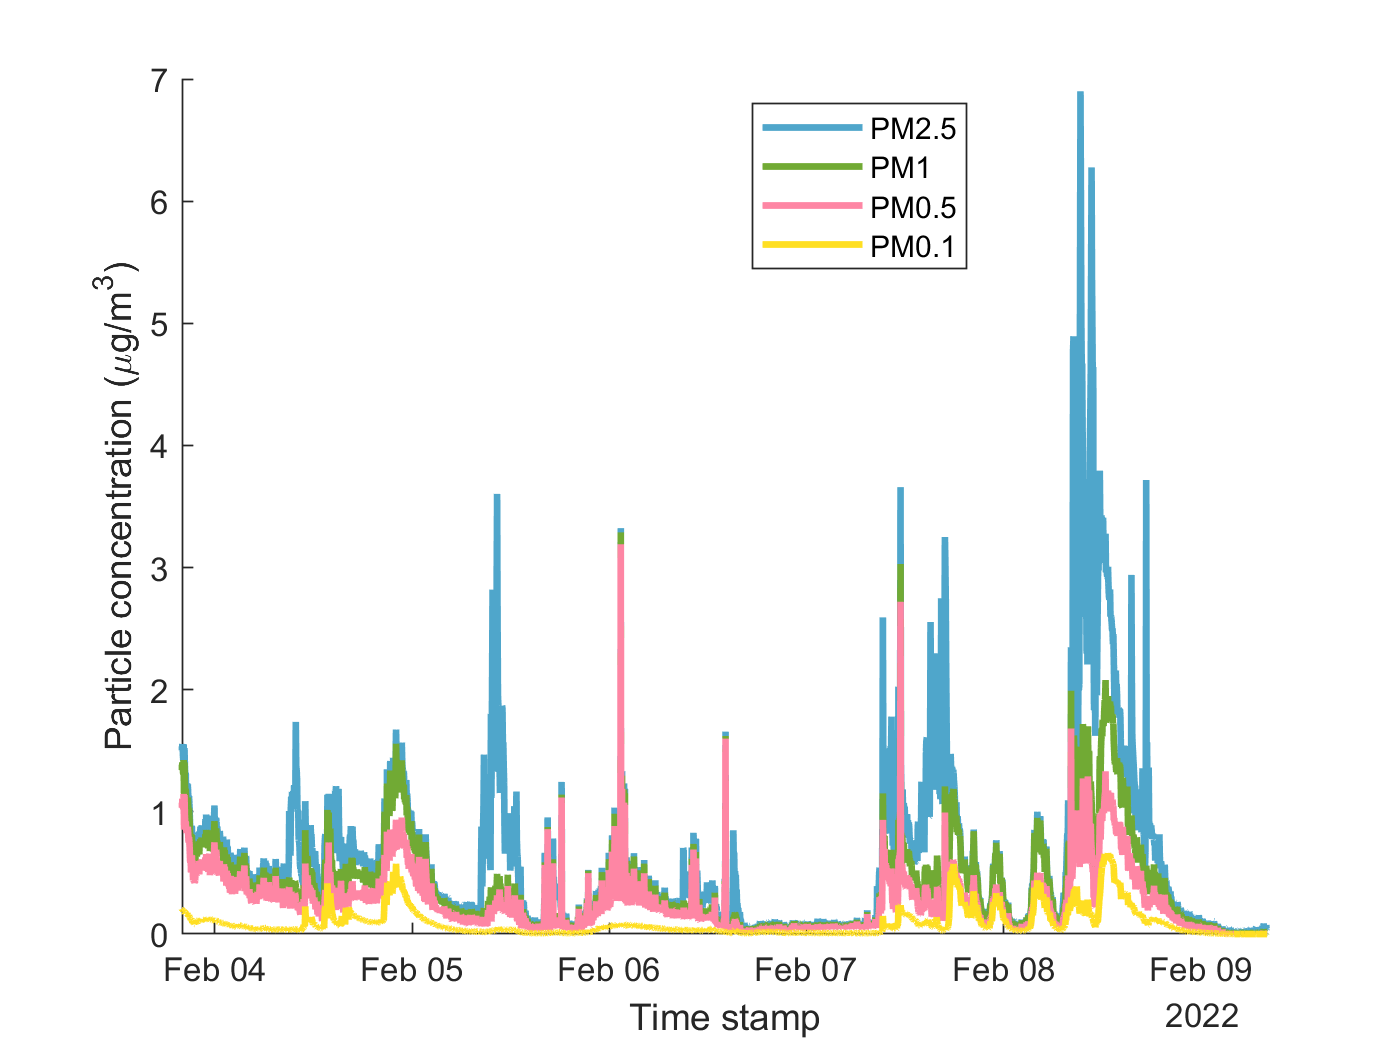

figure(4)
hold on
plot(t_MST_APS,PM2_5,'LineWidth',LW,'Color',lightblue)
plot(t_MST_APS,PM1,'LineWidth',LW,'Color',leaf)
plot(t_MST_SMPS,PM0_5,'LineWidth',LW,'Color',rosa)
plot(t_MST_SMPS,PM0_1,'LineWidth',LW,'Color',sunyellow)

xlabel('Time stamp')
ylabel('Particle concentration (\mug/m^3)')

xlim([datetime(2022,2,3,20,00,0,'TimeZone','America/Denver')...
      datetime(2022,2,9,8,03,0,'TimeZone','America/Denver')])

legend('PM2.5', 'PM1', 'PM0.5', 'PM0.1','location','best')

hold off